alpha=1+mod(964,3);

Q1

alpha=1+mod(964,3);
fsam=720;
fp=10/(fsam/2);
fs=20/(fsam/2);
[nb,wnb]=buttord(fp,fs,-alpha,40);
[z,p,k]=butter(nb,wnb,"low")

z =     -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1


p =    0.9078 + 0.0175i
   0.9078 - 0.0175i
   0.9201 + 0.0504i
   0.9201 - 0.0504i
   0.9437 + 0.0774i
   0.9437 - 0.0774i
   0.9765 + 0.0945i
   0.9765 - 0.0945i


k = 2.6677e-11

[b,a]=butter(nb,wnb,"low","z");
G=filt(b,a,1/fsam)

G =
 
                                                                                               
  2.668e-11 + 2.134e-10 z^-1 + 7.47e-10 z^-2 + 1.494e-09 z^-3 + 1.867e-09 z^-4 + 1.494e-09 z^  
                                                                                               
                                           -5 + 7.47e-10 z^-6 + 2.134e-10 z^-7 + 2.668e-11 z^-8
                                                                                               
  ---------------------------------------------------------------------------------------------
                                                                                               
  1 - 7.496 z^-1 + 24.6 z^-2 - 46.15 z^-3 + 54.15 z^-4 - 40.69 z^-5 + 19.12 z^-6 - 5.136 z^-7  
                                                                                               
                                                                                   + 0.604 z^-8
                                  

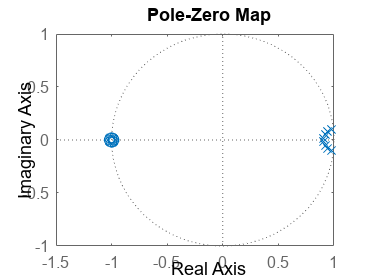

pzmap(G)

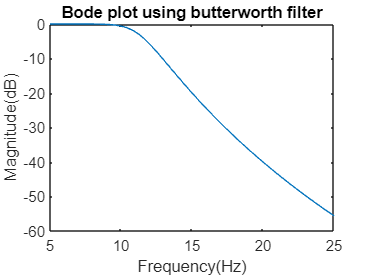

f=linspace(5,25,100);
figure;[mag,ph]=bode(G,2*pi*f);
plot(f,db(squeeze(mag)))
xlabel("Frequency(Hz)")
ylabel("Magnitude(dB)")
title("Bode plot using butterworth filter")

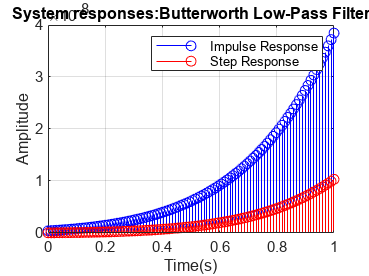

%impulse response
dur = linspace(0,1,100);
h= impulse(b, a,dur);
stem(dur, h,'b');
hold on
% Step response
s= step(b, a,dur);
stem(dur, s, 'r');
hold off

legend('Impulse Response','Step Response');
xlabel('Time(s)');
ylabel('Amplitude');
title('System responses:Butterworth Low-Pass Filter');
grid on;

Q2

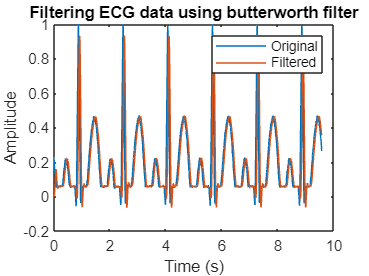

clear
data=load("ECG_Data.txt");
fsam=720;
wn=10/(720/2);
n=4;
[b,a]=butter(n,wn,"low");
filtered_data = filter(b, a, data);
t = (0:length(data)-1) / fsam;
figure;
plot(t, data);
xlabel('Time (s)');
ylabel('Amplitude');
hold on
plot(t, filtered_data);
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original', 'Filtered');
title('Filtering ECG data using butterworth filter')
hold off

Q3

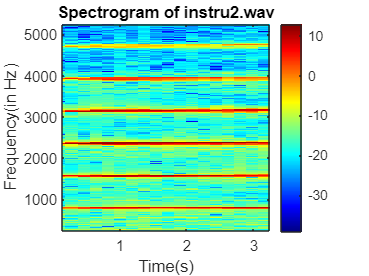

clear
alpha=2;
[s1,fs1]=audioread("instru2.wav");

overlap=900;
N=2000;
[S1,F1,T1]=spectrogram(s1,hamming(N),10,1000,fs1,"xaxis");
imagesc(T1,F1,10*log10(abs(S1)));
axis xy;
colorbar;
colormap('jet')
xlabel('Time(s)')
ylabel('Frequency(in Hz)')
title('Spectrogram of instru2.wav')


y1=fft(s1);
ly1=length(y1);
f_vec1=(0:ly1-1)*fs1/ly1;
[~, idx1] = max(abs(y1));
fund1= f_vec1(idx1)

fund1 = 2.3691e+03

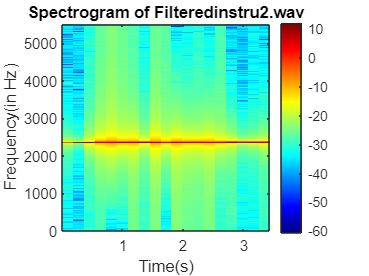

start=[2360 2370]/(fs1/2);
stop=[2340 2390]/(fs1/2);
[n,wn]=buttord(start,stop,-3,60);
[b,a]=butter(n,wn,'bandpass');
filterinstru=filter(b,a,s1);
audiowrite("Filteredinstru2.wav",filterinstru,fs1)

[s2,fs2]=audioread("Filteredinstru2.wav");
[S2,F2,T2]=spectrogram(s2,hamming(N),10,1000,fs2,"xaxis");
imagesc(T2,F2,10*log10(abs(S2)));
axis xy;
colorbar;
colormap('jet')
xlabel('Time(s)')
ylabel('Frequency(in Hz)')
title('Spectrogram of Filteredinstru2.wav')

y2=fft(s2);
ly2=length(y2);
f_vec2=(0:ly2-1)*fs2/ly2;
[~, idx2] = max(abs(y2));
fund2= f_vec2(idx2)

fund2 = 2.3691e+03

Q4

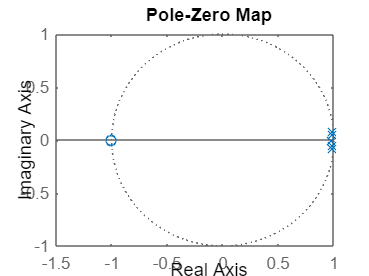

alpha=1+mod(964,3);
fsam=720;
fp=10/(fsam/2);
fs=20/(fsam/2);
[nc,wnc]=cheb1ord(fp,fs,alpha,40);
[z,p,k]=cheby1(nc,alpha,fp,'low');
[bc,ac]=cheby1(nc,alpha,fp,'low',"z");
Gc=filt(bc,ac,1/fsam);
pzmap(Gc)

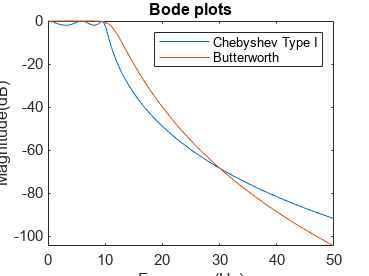


[nb,wnb]=buttord(fp,fs,-alpha,40);
[bb,ab]=butter(nb,wnb,"low","z");
Gb=filt(bb,ab,1/fsam);

f=linspace(0,50,100);
% bodeplot(Gc,Gb,2*pi*f);
[magc,~]=bode(Gc,2*pi*f);
[magb,~]=bode(Gb,2*pi*f);
plot(f,db(squeeze(magc)),f,db(squeeze(magb)))
xlabel("Frequency(Hz)")
ylabel("Magnitude(dB)")
title("Bode plots")
legend("Chebyshev Type I","Butterworth")

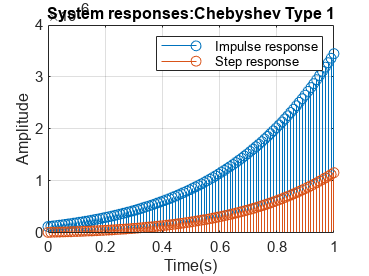


%impulse response
dur=linspace(0,1,100);
h=impulse(bc,ac,dur);
figure;stem(dur,h)
hold on
%step response
s=step(bc,ac,dur);
stem(dur,s)

legend("Impulse response","Step response")
xlabel("Time(s)")
ylabel("Amplitude")
title("System responses:Chebyshev Type 1")
grid on;
hold off